## Fourier Series Calculator


syms x n w

assume(n,{'positive','integer'})
assume(w<1/2)
assumeAlso(w>-1/2)

f=heaviside(x-1/2+w)-heaviside(x-1/2-w)  %initial func

$$f = \mathrm{heaviside}\left(w+x-\frac{1}{2}\right)-\mathrm{heaviside}\left(x-w-\frac{1}{2}\right)$$

interval=[-1/2,1.5]  %%func interval

interval =    -0.5000    1.5000



T=range(interval)  %time period

T = 2


theta=2*pi*x/T  %%theta

$$theta = \pi \,x$$


fplot(subs(f,w,1/8),interval)
a_n=2/T*simplify(int(f*cos(theta*n),interval))

$$a\_n = \frac{2\,\sin\left(\pi \,n\,w\right)\,\cos\left(\frac{\pi \,n}{2}\right)}{n\,\pi }$$

b_n=2/T*simplify(int(f*sin(theta*n),interval))

$$b\_n = \frac{2\,\sin\left(\pi \,n\,w\right)\,\sin\left(\frac{\pi \,n}{2}\right)}{n\,\pi }$$


for i=1:20
    a_set(1,i)=sym(subs(a_n,n,i))*cos(theta*i);
    b_set(1,i)=sym(subs(b_n,n,i))*sin(theta*i);
end

DC=int(f,x,interval)/T

$$DC = w$$

a_set

$$a\_set = \left(\begin{array}{cccccccccccccccccccc} 0 & -\frac{\cos\left(2\,\pi \,x\right)\,\sin\left(2\,\pi \,w\right)}{\pi } & 0 & \frac{\cos\left(4\,\pi \,x\right)\,\sin\left(4\,\pi \,w\right)}{2\,\pi } & 0 & -\frac{\cos\left(6\,\pi \,x\right)\,\sin\left(6\,\pi \,w\right)}{3\,\pi } & 0 & \frac{\cos\left(8\,\pi \,x\right)\,\sin\left(8\,\pi \,w\right)}{4\,\pi } & 0 & -\frac{\cos\left(10\,\pi \,x\right)\,\sin\left(10\,\pi \,w\right)}{5\,\pi } & 0 & \frac{\cos\left(12\,\pi \,x\right)\,\sin\left(12\,\pi \,w\right)}{6\,\pi } & 0 & -\frac{\cos\left(14\,\pi \,x\right)\,\sin\left(14\,\pi \,w\right)}{7\,\pi } & 0 & \frac{\cos\left(16\,\pi \,x\right)\,\sin\left(16\,\pi \,w\right)}{8\,\pi } & 0 & -\frac{\cos\left(18\,\pi \,x\right)\,\sin\left(18\,\pi \,w\right)}{9\,\pi } & 0 & \frac{\cos\left(20\,\pi \,x\right)\,\sin\left(20\,\pi \,w\right)}{10\,\pi } \end{array}\right)$$

b_set

$$b\_set = \left(\begin{array}{cccccccccccccccccccc} \frac{2\,\sin\left(\pi \,w\right)\,\sin\left(\pi \,x\right)}{\pi } & 0 & -\frac{2\,\sin\left(3\,\pi \,w\right)\,\sin\left(3\,\pi \,x\right)}{3\,\pi } & 0 & \frac{2\,\sin\left(5\,\pi \,w\right)\,\sin\left(5\,\pi \,x\right)}{5\,\pi } & 0 & -\frac{2\,\sin\left(7\,\pi \,w\right)\,\sin\left(7\,\pi \,x\right)}{7\,\pi } & 0 & \frac{2\,\sin\left(9\,\pi \,w\right)\,\sin\left(9\,\pi \,x\right)}{9\,\pi } & 0 & -\frac{2\,\sin\left(11\,\pi \,w\right)\,\sin\left(11\,\pi \,x\right)}{11\,\pi } & 0 & \frac{2\,\sin\left(13\,\pi \,w\right)\,\sin\left(13\,\pi \,x\right)}{13\,\pi } & 0 & -\frac{2\,\sin\left(15\,\pi \,w\right)\,\sin\left(15\,\pi \,x\right)}{15\,\pi } & 0 & \frac{2\,\sin\left(17\,\pi \,w\right)\,\sin\left(17\,\pi \,x\right)}{17\,\pi } & 0 & -\frac{2\,\sin\left(19\,\pi \,w\right)\,\sin\left(19\,\pi \,x\right)}{19\,\pi } & 0 \end{array}\right)$$


f2=simplify(DC)+simplify(sum(a_set))+simplify(sum(b_set))

$$f2 = w+\frac{2\,\left(14549535\,\sin\left(\pi \,w\right)\,\sin\left(\pi \,x\right)-4849845\,\sin\left(3\,\pi \,w\right)\,\sin\left(3\,\pi \,x\right)+2909907\,\sin\left(5\,\pi \,w\right)\,\sin\left(5\,\pi \,x\right)-2078505\,\sin\left(7\,\pi \,w\right)\,\sin\left(7\,\pi \,x\right)+1616615\,\sin\left(9\,\pi \,w\right)\,\sin\left(9\,\pi \,x\right)-1322685\,\sin\left(11\,\pi \,w\right)\,\sin\left(11\,\pi \,x\right)+1119195\,\sin\left(13\,\pi \,w\right)\,\sin\left(13\,\pi \,x\right)-969969\,\sin\left(15\,\pi \,w\right)\,\sin\left(15\,\pi \,x\right)+855855\,\sin\left(17\,\pi \,w\right)\,\sin\left(17\,\pi \,x\right)-765765\,\sin\left(19\,\pi \,w\right)\,\sin\left(19\,\pi \,x\right)\right)}{14549535\,\pi }-\frac{2520\,\cos\left(2\,\pi \,x\right)\,\sin\left(2\,\pi \,w\right)-1260\,\cos\left(4\,\pi \,x\right)\,\sin\left(4\,\pi \,w\right)+840\,\cos\left(6\,\pi \,x\right)\,\sin\left(6\,\pi \,w\right)-630\,\cos\left(8\,\pi \,x\right)\,\sin\left(8\,\pi \,w\right)+504\,\cos\left(10\,\pi \,x\right)\,\sin\left(10\,\pi \,w\right)-420\,\cos\left(12\,\pi \,x\right)\,\sin\left(12\,\pi \,w\right)+360\,\cos\left(14\,\pi \,x\right)\,\sin\left(14\,\pi \,w\right)-315\,\cos\left(16\,\pi \,x\right)\,\sin\left(16\,\pi \,w\right)+280\,\cos\left(18\,\pi \,x\right)\,\sin\left(18\,\pi \,w\right)-252\,\cos\left(20\,\pi \,x\right)\,\sin\left(20\,\pi \,w\right)}{2520\,\pi }$$

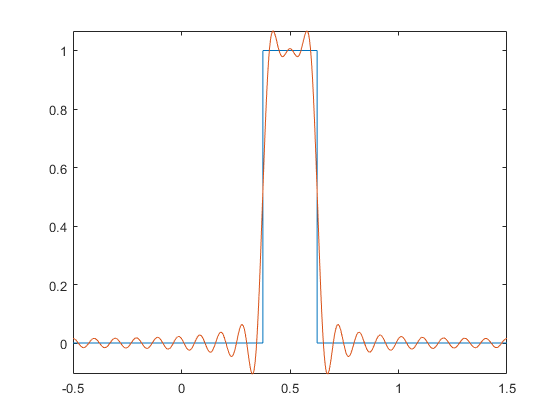


hold on 
fplot(subs(f2,w,1/8),interval)